format long
syms x
p_sym = (1/1296)*x^5 + (5/324)*x^4 + (25/216)*x^3 + (125/324)*x^2 - x + (625/1296);
lambda_sym = solve(p_sym, x);
l_1 = double(lambda_sym(1))

l_1 =      1


l_2 = double(lambda_sym(2))

l_2 =    0.766921747875101


l_3 = double(lambda_sym(3))

l_3 =  -5.050437395158176 - 6.659529125552112i


l_4 = double(lambda_sym(4))

l_4 =  -5.050437395158176 + 6.659529125552112i


l_5 = double(lambda_sym(5))

l_5 =  -11.666046957558750


C1 =   -0.071505663318199


C2 =    1.071505663316907


C3 =       6.591073888827531e-13 + 7.951127685328290e-13i


C4 =       6.591073888827531e-13 - 7.951127685328290e-13i


C5 =     -2.637741988391528e-14


r_W =    1.000000000000000
   0.750255332855114
   0.558720716063973
   0.411828654316954
   0.299173933573923
   0.212776529219576
   0.146517205505455
   0.095698174782212
   0.056700032457810
   0.027343765652879


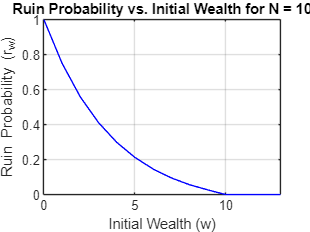

C1 =     -1.638282589683000e-06


C2 =    1.000001638282590


C3 =      -3.967700909787630e-55 + 3.064358024995342e-54i


C4 =      -3.967700909787630e-55 - 3.064358024995342e-54i


C5 =     -1.271545429014692e-61


r_W =    1.000000000000000
   0.766921366027059
   0.588168292668190
   0.451078673209760
   0.345941662639168
   0.265309802726007
   0.203471475786985
   0.156046318005239
   0.119674933106009
   0.091780927026454


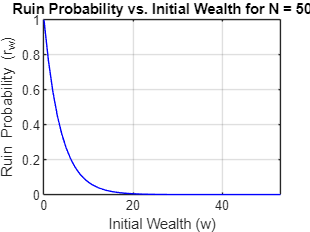

C1 =     -2.831005896281957e-12


C2 =    1.000000000002831


C3 =      3.834198823285929e-106 -1.693424034409224e-106i


C4 =      3.834198823285929e-106 +1.693424034409224e-106i


C5 =    -9.901427893525041e-121


r_W =    1.000000000000000
   0.766921747874442
   0.588168967362635
   0.451079572494985
   0.345942734167948
   0.265311006352114
   0.203472780721406
   0.156047700635208
   0.119676375322384
   0.091782414940940


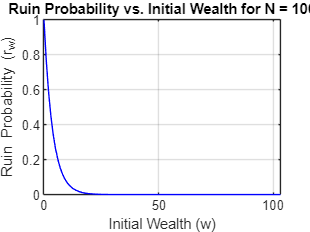


%((c_1)*(l_1)^(W)) + ((c_2)*(l_2)^(W)) + ((c_3)*(l_3)^(W)) + ((c_4)*(l_4)^(W)) + ((c_5)*(l_5)^(W))

N_values = [10, 50, 100]; 
n = length(N_values);

for i = 1:n
    N = N_values(i);

    % Solve for coefficients
    syms c_1 c_2 c_3 c_4 c_5;
    [c_1, c_2, c_3, c_4, c_5] = solve( ...
    ((c_1)*(l_1)^(0)) + ((c_2)*(l_2)^(0)) + ((c_3)*(l_3)^(0)) + ((c_4)*(l_4)^(0)) + ((c_5)*(l_5)^(0)) == 1, ...
    ((c_1)*(l_1)^(N)) + ((c_2)*(l_2)^(N)) + ((c_3)*(l_3)^(N)) + ((c_4)*(l_4)^(N)) + ((c_5)*(l_5)^(N)) == 0, ...
    ((c_1)*(l_1)^(N+1)) + ((c_2)*(l_2)^(N+1)) + ((c_3)*(l_3)^(N+1)) + ((c_4)*(l_4)^(N+1)) + ((c_5)*(l_5)^(N+1)) == 0,  ...
    ((c_1)*(l_1)^(N+2)) + ((c_2)*(l_2)^(N+2)) + ((c_3)*(l_3)^(N+2)) + ((c_4)*(l_4)^(N+2)) + ((c_5)*(l_5)^(N+2)) == 0, ...
    ((c_1)*(l_1)^(N+3)) + ((c_2)*(l_2)^(N+3)) + ((c_3)*(l_3)^(N+3)) + ((c_4)*(l_4)^(N+3)) + ((c_5)*(l_5)^(N+3)) == 0);

    C1 = double(c_1) % Extract values
    C2 = double(c_2)
    C3 = double(c_3)
    C4 = double(c_4)
    C5 = double(c_5)

    r_W = zeros(1, N+4);
   
    for W = 1:N+4
    r_W(W) = ((c_1)*(l_1)^(W-1)) + ((c_2)*(l_2)^(W-1)) + ((c_3)*(l_3)^(W-1)) + ((c_4)*(l_4)^(W-1)) + ((c_5)*(l_5)^(W-1));
    end

    r_W = double(r_W)'

    figure;
    plot(0:N+3, r_W, 'b', 'DisplayName', 'r_w');
    xlabel('Initial Wealth (w)');
    ylabel('Ruin Probability (r_w)');
    title(['Ruin Probability vs. Initial Wealth for N = ', num2str(N)]);
    grid on;
    xlim([0 N+3])
    ylim([0.000 1.000])

end